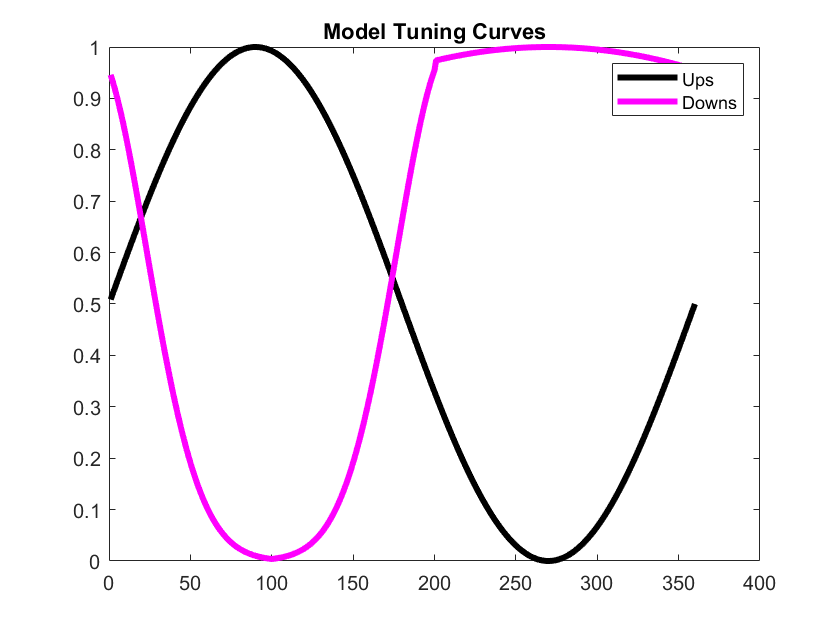

modelUp = @(x) 0.5*sin(x * 2*pi/360) + 0.5; %cosine fit with period 360 deg
modelDown = @(b, c, x) 1*exp(-((x - b).^2)./(2*c.^2)); %gaussian fit

xs = 1:360;
modelUpY = modelUp(xs);
modelDownY = [modelDown(-10,33, 1:100),...
    modelDown(210, 33, 101:200),  modelDown(270, 300, 201:360)]; %down cells are modeled by sum of 3 gaussians (it just approximates the overall shape

figure
plot(xs, modelUpY, '-k', 'LineWidth', 3)
hold on
plot(xs, modelDownY, '-m', 'LineWidth', 3)
title('Model Tuning Curves')
legend('Ups', 'Downs')

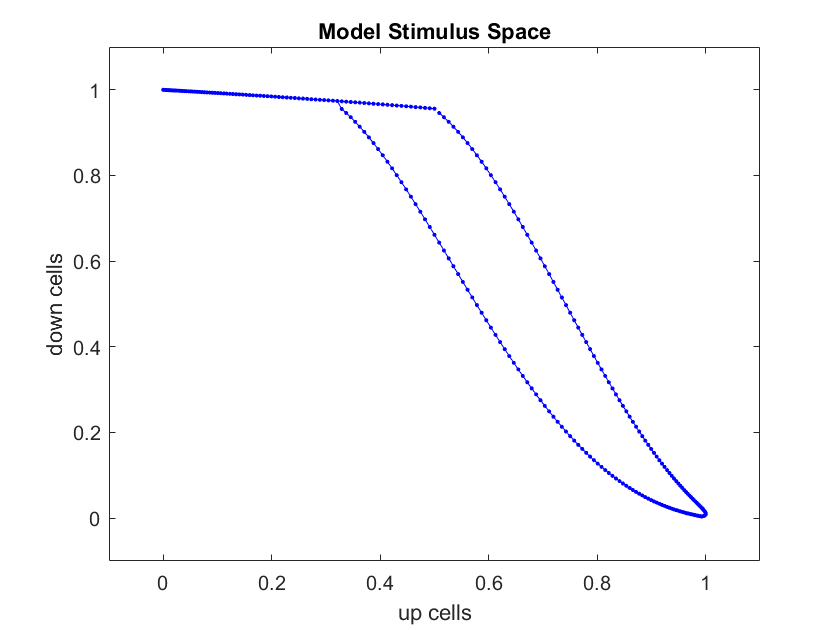


figure
plot(modelUpY, modelDownY, '.-b')
hold on
title('Model Stimulus Space')
xlabel('up cells')
ylabel('down cells')
xlim([-0.1, 1.1])
ylim([-0.1, 1.1])